# MECH 6318 - Homework 8

Name: Jonas Wagner

Date: 2021-11-04

clear
close all

## Problem 15.3

% Data
X = [2; 4; 6; 2; 4; 6; 2; 4; 6];
Y = [3; 3; 3; 5; 5; 5; 7; 7; 7];
F = [-12.12;
     - 5.97;
     -11.98;
     - 8.04;
     - 2.18;
     - 7.97;
     -12.03;
     - 5.97;
     -12.00];

% Fit to RBF
delta = 0.01;
XX = repmat(X,1,size(X,1));
YY = repmat(Y,1,size(X,1));

Psi = sqrt((XX-XX')'.^2 + (YY-YY')'.^2 + delta.^2)

Psi =     0.0100    2.0000    4.0000    2.0000    2.8284    4.4721    4.0000    4.4721    5.6569
    2.0000    0.0100    2.0000    2.8284    2.0000    2.8284    4.4721    4.0000    4.4721
    4.0000    2.0000    0.0100    4.4721    2.8284    2.0000    5.6569    4.4721    4.0000
    2.0000    2.8284    4.4721    0.0100    2.0000    4.0000    2.0000    2.8284    4.4721
    2.8284    2.0000    2.8284    2.0000    0.0100    2.0000    2.8284    2.0000    2.8284
    4.4721    2.8284    2.0000    4.0000    2.0000    0.0100    4.4721    2.8284    2.0000
    4.0000    4.4721    5.6569    2.0000    2.8284    4.4721    0.0100    2.0000    4.0000
    4.4721    4.0000    4.4721    2.8284    2.0000    2.8284    2.0000    0.0100    2.0000
    5.6569    4.4721    4.0000    4.4721    2.8284    2.0000    4.0000    2.0000    0.0100


W = Psi \ F

W =     0.6765
   -1.8153
    0.6368
   -0.5725
   -1.9523
   -0.5701
    0.6394
   -1.7985
    0.6468



h = @(x,y) W' * sqrt((x - X).^2 + (y-Y).^2 + delta.^2)

h = function_handle with value:
    @(x,y)W'*sqrt((x-X).^2+(y-Y).^2+delta.^2)


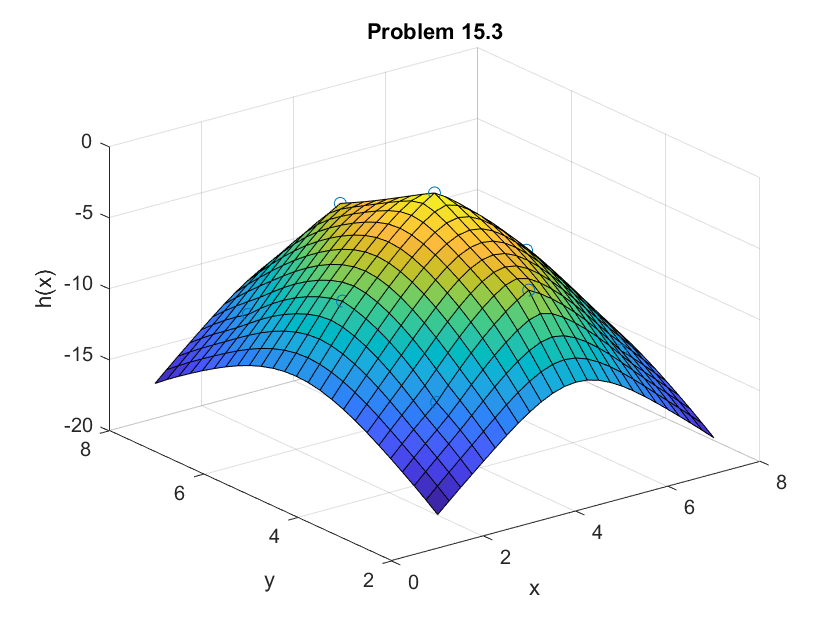

H = @(x,y) arrayfun(h,x,y);

% Plot
[X_mesh,Y_mesh] = meshgrid(1:0.25:7,2:0.25:8);
surf(X_mesh,Y_mesh,arrayfun(H,X_mesh,Y_mesh))
hold on
scatter3(X,Y,F)
title('Problem 15.3')
xlabel('x')
ylabel('y')
zlabel('h(x)')